# 美赛培训第三次课：数学建模常用算法与MATLAB实现

% 授课人：Mr.Guo
% 时间：2小时
% 目标：掌握线性回归、聚类分析等常用建模算法及其MATLAB实现

## 第一部分：课程回顾与目标设定

% 1.1 前两节课回顾
disp('=== 前两节课回顾 ===')

=== 前两节课回顾 ===


disp('第一课：数据类型、描述性统计、SPSS基础')

第一课：数据类型、描述性统计、SPSS基础


disp('第二课：MATLAB基础、数据导入清洗、基本可视化')

第二课：MATLAB基础、数据导入清洗、基本可视化


disp(' ')

disp('我们已经掌握:')

我们已经掌握:


disp('✓ 数据预处理技能')

✓ 数据预处理技能


disp('✓ 基本统计量计算')

✓ 基本统计量计算


disp('✓ MATLAB编程基础')

✓ MATLAB编程基础


disp('✓ 数据可视化方法')

✓ 数据可视化方法



% 1.2 本节课学习目标
disp(' ')

disp('=== 本节课学习目标 ===')

=== 本节课学习目标 ===


disp('1. 掌握线性回归原理与MATLAB实现')

1. 掌握线性回归原理与MATLAB实现


disp('2. 理解并实现K-means聚类算法')

2. 理解并实现K-means聚类算法


disp('3. 学习主成分分析(PCA)降维技术')

3. 学习主成分分析(PCA)降维技术


disp('4. 完成糖尿病风险预测实战案例')

4. 完成糖尿病风险预测实战案例


disp('5. 了解模型评估与验证方法')

5. 了解模型评估与验证方法



% 1.3 准备工作
clear
clc
close all

% 加载糖尿病数据集
disp(' ')

disp('=== 加载数据集 ===')

=== 加载数据集 ===


try
    load('diabetes_data.mat');
    disp('已加载保存的糖尿病数据集')
catch
    % 如果文件不存在，创建模拟数据
    disp('创建模拟糖尿病数据集...')
    rng(42); % 设置随机种子，确保结果可重复
    
    n_samples = 500;
    
    % 生成特征
    age = randi([20, 80], n_samples, 1);
    bmi = 25 + 8*randn(n_samples, 1); % BMI
    glucose = 100 + 40*randn(n_samples, 1); % 空腹血糖
    bp = 80 + 20*randn(n_samples, 1); % 血压
    insulin = 80 + 50*randn(n_samples, 1); % 胰岛素
    skin_thickness = 20 + 10*randn(n_samples, 1); % 皮肤厚度
    
    % 生成目标变量（糖尿病风险评分）
    % 使用线性组合加上一些噪声
    diabetes_risk = 0.3*age/80 + 0.2*(bmi-25)/10 + 0.3*(glucose-100)/50 + ...
                    0.1*(bp-80)/20 + 0.1*(insulin-80)/50 + 0.05*randn(n_samples, 1);
    
    % 转换为二分类标签（是否患糖尿病）
    diabetes_label = diabetes_risk > 0.5;
    
    % 创建表格
    diabetes_data = table(age, bmi, glucose, bp, insulin, skin_thickness, ...
                         diabetes_risk, diabetes_label, ...
                         'VariableNames', {'Age', 'BMI', 'Glucose', 'BP', ...
                         'Insulin', 'SkinThickness', 'Risk', 'Label'});
    
    % 保存数据以便下次使用
    save('diabetes_data.mat', 'diabetes_data');
    disp('模拟糖尿病数据集创建完成并已保存')
end

已加载保存的糖尿病数据集



% 显示数据基本信息
disp(' ')

disp('数据集基本信息:')

数据集基本信息:


disp(['样本数量: ', num2str(height(diabetes_data))])

样本数量: 500


disp(['特征数量: ', num2str(width(diabetes_data)-2)]) % 减去Risk和Label列

特征数量: 6


disp(' ')

disp('前5行数据:')

前5行数据:


disp(diabetes_data(1:5, :))

    Age     BMI      Glucose      BP      Insulin    SkinThickness      Risk      Label
    ___    ______    _______    ______    _______    _____________    ________    _____

    42     26.615    79.096     99.356     87.543       30.319         0.20185    false
    77     25.667    127.88     82.633     39.231       37.112         0.43949    false
    64     20.771    233.04     74.525      129.5       21.075          1.0439    true 
    56     33.658    58.127     88.623     115.89       12.471          0.2172    false
    29      28.37    108.13     91.825    -12.281       13.286        0.074374    false



## 第二部分：线性回归分析


% 2.1 线性回归原理介绍
disp(' ')

disp('=== 线性回归分析 ===')

=== 线性回归分析 ===


disp('线性回归是建模中最常用的方法之一：')

线性回归是建模中最常用的方法之一：


disp('模型公式: y = β₀ + β₁x₁ + β₂x₂ + ... + βₖxₖ + ε')

模型公式: y = β₀ + β₁x₁ + β₂x₂ + ... + βₖxₖ + ε


disp(' ')

disp('应用场景:')

应用场景:


disp('1. 预测连续型目标变量')

1. 预测连续型目标变量


disp('2. 探索变量间关系')

2. 探索变量间关系


disp('3. 量化特征重要性')

3. 量化特征重要性



% 2.2 简单线性回归示例
disp(' ')

disp('--- 简单线性回归示例 ---')

--- 简单线性回归示例 ---


disp('研究BMI对糖尿病风险的影响')

研究BMI对糖尿病风险的影响



% 准备数据
X_simple = diabetes_data.BMI;
y_simple = diabetes_data.Risk;

% 使用polyfit进行简单线性回归
p = polyfit(X_simple, y_simple, 1); % 1表示一次多项式（线性）
y_fit = polyval(p, X_simple);

% 计算R²
SS_res = sum((y_simple - y_fit).^2);
SS_tot = sum((y_simple - mean(y_simple)).^2);
R2_simple = 1 - SS_res/SS_tot;

% 可视化
figure('Position', [100, 100, 1200, 400])

subplot(1, 3, 1)
scatter(X_simple, y_simple, 30, 'filled', 'MarkerFaceAlpha', 0.6, 'MarkerEdgeColor', 'k')
hold on
plot(X_simple, y_fit, 'r-', 'LineWidth', 2)
xlabel('BMI')
ylabel('糖尿病风险')
title(['简单线性回归: y = ', num2str(p(1), '%.4f'), 'x + ', num2str(p(2), '%.4f')])
legend('数据点', '回归线', 'Location', 'best')
grid on

% 添加回归方程和R²
text(min(X_simple), max(y_simple)*0.9, ...
    sprintf('R² = %.4f\np₁ = %.4f', R2_simple, p(1)), ...
    'FontSize', 10, 'BackgroundColor', 'white')

% 2.3 多元线性回归
disp(' ')

disp('--- 多元线性回归示例 ---')

--- 多元线性回归示例 ---


disp('使用多个特征预测糖尿病风险')

使用多个特征预测糖尿病风险



% 准备数据
X_multi = [diabetes_data.Age, diabetes_data.BMI, diabetes_data.Glucose, ...
           diabetes_data.BP, diabetes_data.Insulin];
y_multi = diabetes_data.Risk;

% 添加常数项（截距）
X_multi_with_const = [ones(size(X_multi, 1), 1), X_multi];

% 使用矩阵方法计算回归系数
% β = (X'X)^(-1) X'y
beta = (X_multi_with_const' * X_multi_with_const) \ (X_multi_with_const' * y_multi);

% 预测值
y_pred_multi = X_multi_with_const * beta;

% 计算统计量
n = size(X_multi, 1); % 样本数
k = size(X_multi, 2); % 特征数（不含常数项）

% R²
SS_res_multi = sum((y_multi - y_pred_multi).^2);
SS_tot_multi = sum((y_multi - mean(y_multi)).^2);
R2_multi = 1 - SS_res_multi/SS_tot_multi;

% 调整R²
R2_adj = 1 - (1-R2_multi)*(n-1)/(n-k-1);

% 残差
residuals = y_multi - y_pred_multi;

% 显示结果
disp('回归系数:')

回归系数:


var_names = {'截距', '年龄', 'BMI', '血糖', '血压', '胰岛素'};
for i = 1:length(beta)
    disp(['  ', var_names{i}, ': ', num2str(beta(i), '%.6f')])
end

  截距: -1.658987
  年龄: 0.004034
  BMI: 0.019679
  血糖: 0.006033
  血压: 0.004906
  胰岛素: 0.001972


disp(' ')

disp(['R²: ', num2str(R2_multi, '%.4f')])

R²: 0.9787


disp(['调整R²: ', num2str(R2_adj, '%.4f')])

调整R²: 0.9785


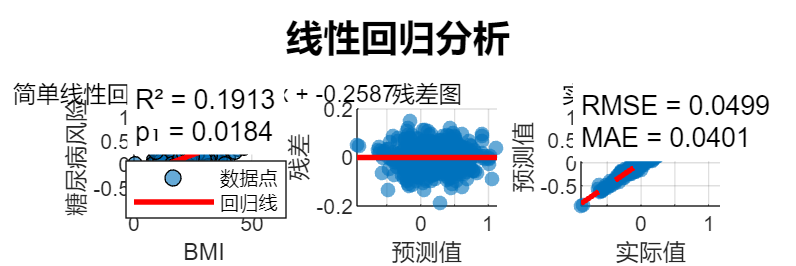


% 2.4 多元回归可视化
% 残差分析
subplot(1, 3, 2)
scatter(y_pred_multi, residuals, 30, 'filled', 'MarkerFaceAlpha', 0.6)
hold on
plot([min(y_pred_multi), max(y_pred_multi)], [0, 0], 'r-', 'LineWidth', 2)
xlabel('预测值')
ylabel('残差')
title('残差图')
grid on

% 添加零参考线
plot([min(y_pred_multi), max(y_pred_multi)], [0, 0], 'r-', 'LineWidth', 1)

% 实际值 vs 预测值
subplot(1, 3, 3)
scatter(y_multi, y_pred_multi, 30, 'filled', 'MarkerFaceAlpha', 0.6)
hold on
plot([min(y_multi), max(y_multi)], [min(y_multi), max(y_multi)], 'r--', 'LineWidth', 2)
xlabel('实际值')
ylabel('预测值')
title('实际值 vs 预测值')
grid on

% 计算并显示均方误差
MSE = mean(residuals.^2);
RMSE = sqrt(MSE);
MAE = mean(abs(residuals));

text(min(y_multi), max(y_pred_multi)*0.8, ...
    sprintf('RMSE = %.4f\nMAE = %.4f', RMSE, MAE), ...
    'FontSize', 10, 'BackgroundColor', 'white')

sgtitle('线性回归分析', 'FontSize', 14, 'FontWeight', 'bold')


% 2.5 使用MATLAB内置函数进行回归
disp(' ')

disp('--- 使用MATLAB内置函数 ---')

--- 使用MATLAB内置函数 ---


disp('fitlm函数提供更完整的回归分析')

fitlm函数提供更完整的回归分析



% 使用fitlm
mdl = fitlm(X_multi, y_multi, 'VarNames', {'Age', 'BMI', 'Glucose', 'BP', 'Insulin', 'Risk'});

% 显示回归结果
disp(' ')

disp('回归模型摘要:')

回归模型摘要:


disp(mdl)

线性回归模型:
    Risk ~ 1 + Age + BMI + Glucose + BP + Insulin

估计系数:
                   Estimate         SE         tStat       pValue   
                   _________    __________    _______    ___________

    (Intercept)       -1.659       0.01492    -111.19              0
    Age            0.0040338    0.00012372     32.604    3.1017e-125
    BMI             0.019679    0.00027682     71.091    1.3326e-261
    Glucose        0.0060331    5.3119e-05     113.58              0
    BP             0.0049057    0.00012119     40.479    5.3209e-159
    Insulin        0.0019719    4.4475e-05     44.336    2.5545e-174


观测值数目: 500，误差自由度: 494
均方根误差: 0.0502
R 方: 0.979，调整 R 方 0.978
F 统计量(常量模型): 4.53e+03，p 值 = 0



% 显示ANOVA表
disp(' ')

disp('ANOVA表:')

ANOVA表:


anova(mdl, 'summary')

ans = 3×5 table
                SumSq     DF      MeanSq        F       pValue
                ______    ___    _________    ______    ______

    Total       58.467    499      0.11717                    
    Model        57.22      5       11.444    4534.7       0  
    Residual    1.2467    494    0.0025237                    



% 2.6 特征重要性分析
disp(' ')

disp('--- 特征重要性分析 ---')

--- 特征重要性分析 ---



% 提取t统计量
t_stats = mdl.Coefficients.tStat(2:end); % 排除截距
p_values = mdl.Coefficients.pValue(2:end);

% 创建特征重要性表格
feature_names = {'Age', 'BMI', 'Glucose', 'BP', 'Insulin'};
importance_table = table(feature_names', t_stats, p_values, ...
    'VariableNames', {'Feature', 'tStat', 'pValue'});

% 按t统计量绝对值排序
[~, idx] = sort(abs(t_stats), 'descend');
importance_table = importance_table(idx, :);

disp('特征重要性排序（按|t|值）:')

特征重要性排序（按|t|值）:


disp(importance_table)

      Feature      tStat       pValue   
    ___________    ______    ___________

    {'Glucose'}    113.58              0
    {'BMI'    }    71.091    1.3326e-261
    {'Insulin'}    44.336    2.5545e-174
    {'BP'     }    40.479    5.3209e-159
    {'Age'    }    32.604    3.1017e-125



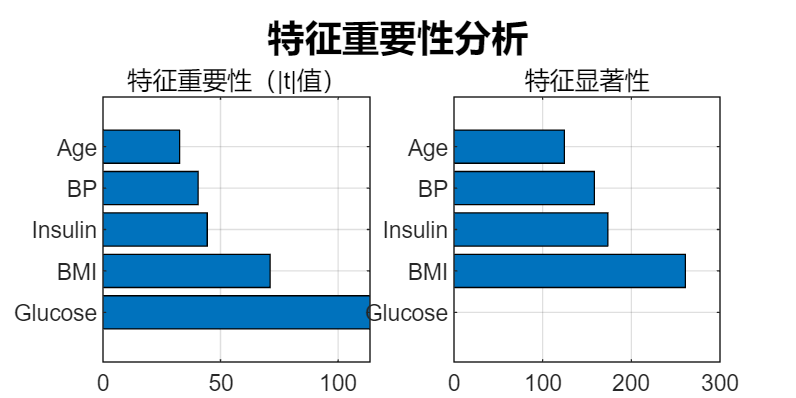


% 可视化特征重要性
figure('Position', [100, 100, 800, 400])

subplot(1, 2, 1)
barh(abs(t_stats(idx)))
set(gca, 'YTick', 1:length(feature_names))
set(gca, 'YTickLabel', feature_names(idx))
xlabel('|t统计量|')
title('特征重要性（|t|值）')
grid on

subplot(1, 2, 2)
barh(-log10(p_values(idx)))
set(gca, 'YTick', 1:length(feature_names))
set(gca, 'YTickLabel', feature_names(idx))
xlabel('-log₁₀(p值)')
title('特征显著性')
grid on

sgtitle('特征重要性分析', 'FontSize', 14, 'FontWeight', 'bold')

## 第三部分：聚类分析


% 3.1 聚类分析原理
disp(' ')

disp('=== 聚类分析 ===')

=== 聚类分析 ===


disp('聚类是无监督学习方法，用于发现数据内在结构')

聚类是无监督学习方法，用于发现数据内在结构


disp('K-means算法步骤:')

K-means算法步骤:


disp('1. 随机初始化K个聚类中心')

1. 随机初始化K个聚类中心


disp('2. 将每个点分配到最近的聚类中心')

2. 将每个点分配到最近的聚类中心


disp('3. 重新计算聚类中心')

3. 重新计算聚类中心


disp('4. 重复2-3直到收敛')

4. 重复2-3直到收敛



% 3.2 K-means聚类实现
disp(' ')

disp('--- K-means聚类示例 ---')

--- K-means聚类示例 ---


disp('对糖尿病患者进行分群')

对糖尿病患者进行分群



% 选择用于聚类的特征
X_cluster = [diabetes_data.Age, diabetes_data.BMI, diabetes_data.Glucose, diabetes_data.BP];

% 数据标准化（重要步骤！）
X_cluster_scaled = zscore(X_cluster);

% 确定最佳K值（肘部法则）
disp('确定最佳K值（肘部法则）...')

确定最佳K值（肘部法则）...



max_k = 10;
inertia = zeros(max_k, 1);

for k = 1:max_k
    [~, ~, sumd] = kmeans(X_cluster_scaled, k, 'Replicates', 10, 'MaxIter', 100);
    inertia(k) = sum(sumd);
end

% 肘部法则可视化
figure('Position', [100, 100, 1200, 400])

subplot(1, 3, 1)
plot(1:max_k, inertia, 'bo-', 'LineWidth', 2, 'MarkerSize', 8, 'MarkerFaceColor', 'b')
xlabel('聚类数量 K')
ylabel('类内平方和（惯性）')
title('肘部法则')
grid on

% 添加肘部点标记（通常选择拐点）
hold on
% 计算二阶差分找到拐点
diff2 = diff(diff(inertia));
[~, elbow_point] = max(abs(diff2));
elbow_point = elbow_point + 2; % 调整索引
plot(elbow_point, inertia(elbow_point), 'ro', 'MarkerSize', 12, 'MarkerFaceColor', 'r')
legend('惯性值', '建议K值', 'Location', 'best')

% 3.3 执行K-means聚类
optimal_k = elbow_point;
disp(['建议聚类数量: K = ', num2str(optimal_k)])

建议聚类数量: K = 3



% 执行K-means
[idx, C, sumd] = kmeans(X_cluster_scaled, optimal_k, ...
    'Replicates', 20, 'MaxIter', 200, 'Display', 'final');

第 1 次重复，24 次迭代，总距离 = 1375.33。
第 2 次重复，26 次迭代，总距离 = 1387.6。
第 3 次重复，28 次迭代，总距离 = 1399.12。
第 4 次重复，27 次迭代，总距离 = 1383.01。
第 5 次重复，13 次迭代，总距离 = 1386.47。
第 6 次重复，21 次迭代，总距离 = 1415.26。
第 7 次重复，12 次迭代，总距离 = 1389.66。
第 8 次重复，25 次迭代，总距离 = 1376.52。
第 9 次重复，9 次迭代，总距离 = 1393.33。
第 10 次重复，19 次迭代，总距离 = 1378.46。
第 11 次重复，12 次迭代，总距离 = 1383.32。
第 12 次重复，19 次迭代，总距离 = 1387.3。
第 13 次重复，27 次迭代，总距离 = 1375.47。
第 14 次重复，33 次迭代，总距离 = 1415.12。
第 15 次重复，51 次迭代，总距离 = 1386.05。
第 16 次重复，16 次迭代，总距离 = 1412.92。
第 17 次重复，11 次迭代，总距离 = 1384.52。
第 18 次重复，15 次迭代，总距离 = 1386.5。
第 19 次重复，23 次迭代，总距离 = 1394.29。
第 20 次重复，10 次迭代，总距离 = 1387.62。
距离的最佳总和 = 1375.33


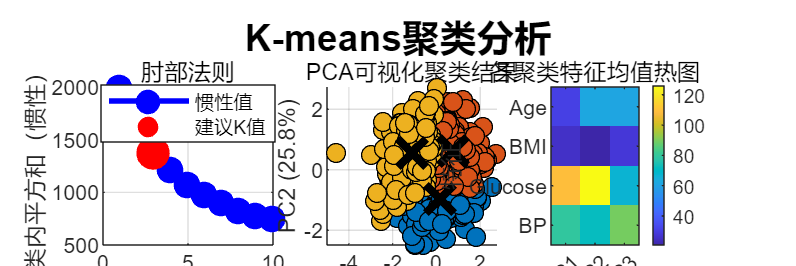


% 将聚类结果添加到数据表
diabetes_data.Cluster = idx;

% 3.4 聚类结果可视化
% 主成分分析用于可视化高维聚类
[coeff, score, ~, ~, explained] = pca(X_cluster_scaled);

% 前两个主成分的散点图
subplot(1, 3, 2)
colors = lines(optimal_k); % 生成不同颜色
for i = 1:optimal_k
    scatter(score(idx==i, 1), score(idx==i, 2), 50, colors(i, :), ...
        'filled', 'MarkerEdgeColor', 'k', 'LineWidth', 0.5)
    hold on
end

% 绘制聚类中心在PCA空间中的位置
C_pca = C * coeff(:, 1:2);
plot(C_pca(:, 1), C_pca(:, 2), 'kx', 'MarkerSize', 15, 'LineWidth', 3)

xlabel(['PC1 (', num2str(explained(1), '%.1f'), '%)'])
ylabel(['PC2 (', num2str(explained(2), '%.1f'), '%)'])
title('PCA可视化聚类结果')
% legend(arrayfun(@(x) sprintf('Cluster %d', x), 1:optimal_k, 'UniformOutput', false), ...
    % 'Cluster Centers', 'Location', 'best')
grid on

% 3.5 聚类特征分析
subplot(1, 3, 3)

% 计算每个聚类的特征均值
cluster_means = zeros(optimal_k, size(X_cluster, 2));
for i = 1:optimal_k
    cluster_means(i, :) = mean(X_cluster(idx==i, :), 1);
end

% 热图显示聚类特征
imagesc(cluster_means')
colorbar
set(gca, 'XTick', 1:optimal_k)
set(gca, 'XTickLabel', arrayfun(@(x) sprintf('C%d', x), 1:optimal_k, 'UniformOutput', false))
set(gca, 'YTick', 1:size(X_cluster, 2))
set(gca, 'YTickLabel', {'Age', 'BMI', 'Glucose', 'BP'})
title('各聚类特征均值热图')
ylabel('特征')

sgtitle('K-means聚类分析', 'FontSize', 14, 'FontWeight', 'bold')


% 3.6 聚类结果解释
disp(' ')

disp('--- 聚类结果解释 ---')

--- 聚类结果解释 ---


disp('各聚类特征分析:')

各聚类特征分析:



feature_names_cluster = {'Age', 'BMI', 'Glucose', 'BP'};
for i = 1:optimal_k
    cluster_size = sum(idx == i);
    disp(['聚类 ', num2str(i), ' (', num2str(cluster_size), ' 个样本, ', ...
        num2str(100*cluster_size/length(idx), '%.1f'), '%):'])
    
    for j = 1:length(feature_names_cluster)
        feature_mean = mean(X_cluster(idx==i, j));
        feature_std = std(X_cluster(idx==i, j));
        disp(['  ', feature_names_cluster{j}, ': ', ...
            num2str(feature_mean, '%.1f'), ' ± ', num2str(feature_std, '%.1f')])
    end
    
    % 计算该聚类的平均糖尿病风险
    cluster_risk = mean(diabetes_data.Risk(idx==i));
    cluster_diabetes_rate = mean(diabetes_data.Label(idx==i));
    disp(['  平均风险: ', num2str(cluster_risk, '%.3f')])
    disp(['  糖尿病比例: ', num2str(100*cluster_diabetes_rate, '%.1f'), '%'])
    disp(' ')
end

聚类 1 (193 个样本, 38.6%):


  Age: 31.1 ± 8.0
  BMI: 25.4 ± 7.4
  Glucose: 109.0 ± 35.4
  BP: 79.2 ± 18.5


  平均风险: 0.164


  糖尿病比例: 15.0%


聚类 2 (159 个样本, 31.8%):


  Age: 62.1 ± 10.6
  BMI: 20.9 ± 7.3
  Glucose: 125.8 ± 36.2
  BP: 71.8 ± 16.2


  平均风险: 0.273


  糖尿病比例: 22.0%


聚类 3 (148 个样本, 29.6%):


  Age: 61.4 ± 12.9
  BMI: 28.1 ± 8.3
  Glucose: 66.9 ± 34.6
  BP: 89.3 ± 17.0


  平均风险: 0.156


  糖尿病比例: 17.6%


## 第四部分：主成分分析(PCA)


% 4.1 PCA原理介绍
disp(' ')

disp('=== 主成分分析(PCA) ===')

=== 主成分分析(PCA) ===


disp('PCA用于降维和特征提取:')

PCA用于降维和特征提取:


disp('1. 减少特征数量，避免维度灾难')

1. 减少特征数量，避免维度灾难


disp('2. 去除特征间相关性')

2. 去除特征间相关性


disp('3. 可视化高维数据')

3. 可视化高维数据



% 4.2 PCA实现与解释
disp(' ')

disp('--- PCA分析示例 ---')

--- PCA分析示例 ---



% 对糖尿病特征进行PCA
X_pca = [diabetes_data.Age, diabetes_data.BMI, diabetes_data.Glucose, ...
         diabetes_data.BP, diabetes_data.Insulin, diabetes_data.SkinThickness];

% 数据标准化
X_pca_scaled = zscore(X_pca);

% 执行PCA
[coeff_pca, score_pca, latent, tsquared, explained_pca] = pca(X_pca_scaled);

% 显示解释方差
disp('主成分解释方差:')

主成分解释方差:


for i = 1:min(6, length(explained_pca))
    disp(['  PC', num2str(i), ': ', num2str(explained_pca(i), '%.2f'), '%'])
end

  PC1: 18.49%
  PC2: 18.08%
  PC3: 17.67%
  PC4: 16.84%
  PC5: 15.50%
  PC6: 13.42%


disp(' ')

disp('累积解释方差:')

累积解释方差:


cum_explained = cumsum(explained_pca);
for i = 1:min(6, length(cum_explained))
    disp(['  前', num2str(i), '个主成分: ', num2str(cum_explained(i), '%.2f'), '%'])
end

  前1个主成分: 18.49%
  前2个主成分: 36.57%
  前3个主成分: 54.25%
  前4个主成分: 71.08%
  前5个主成分: 86.58%
  前6个主成分: 100.00%


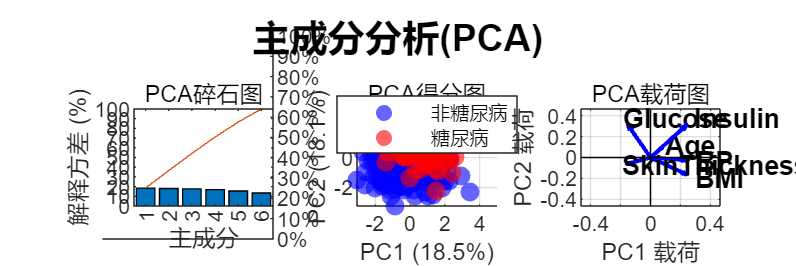


% 4.3 PCA可视化
figure('Position', [100, 100, 1200, 400])

% 碎石图
subplot(1, 3, 1)
pareto(explained_pca)
xlabel('主成分')
ylabel('解释方差 (%)')
title('PCA碎石图')

% 前两个主成分的散点图
subplot(1, 3, 2)
if ismember('Label', diabetes_data.Properties.VariableNames)
    % 按糖尿病标签着色
    diabetic = diabetes_data.Label == 1;
    scatter(score_pca(~diabetic, 1), score_pca(~diabetic, 2), 50, 'b', ...
        'filled', 'MarkerFaceAlpha', 0.6, 'DisplayName', '非糖尿病')
    hold on
    scatter(score_pca(diabetic, 1), score_pca(diabetic, 2), 50, 'r', ...
        'filled', 'MarkerFaceAlpha', 0.6, 'DisplayName', '糖尿病')
    legend('Location', 'best')
else
    scatter(score_pca(:, 1), score_pca(:, 2), 50, 'filled', 'MarkerFaceAlpha', 0.6)
end
xlabel(['PC1 (', num2str(explained_pca(1), '%.1f'), '%)'])
ylabel(['PC2 (', num2str(explained_pca(2), '%.1f'), '%)'])
title('PCA得分图')
grid on

% 载荷图（特征在主成分上的权重）
subplot(1, 3, 3)
feature_names_pca = {'Age', 'BMI', 'Glucose', 'BP', 'Insulin', 'SkinThickness'};

% 绘制箭头
for i = 1:length(feature_names_pca)
    % 缩放载荷以便可视化
    arrow_scale = 0.8 * max(abs(coeff_pca(:)));
    quiver(0, 0, coeff_pca(i, 1)*arrow_scale, coeff_pca(i, 2)*arrow_scale, ...
        'MaxHeadSize', 0.5, 'LineWidth', 1.5, 'Color', 'b')
    hold on
    
    % 添加标签
    text(coeff_pca(i, 1)*arrow_scale*1.1, coeff_pca(i, 2)*arrow_scale*1.1, ...
        feature_names_pca{i}, 'FontSize', 10, 'FontWeight', 'bold')
end

% 设置坐标轴
axis_limit = max(abs(coeff_pca(:))) * arrow_scale * 1.3;
xlim([-axis_limit, axis_limit])
ylim([-axis_limit, axis_limit])

% 添加参考线
plot([-axis_limit, axis_limit], [0, 0], 'k-', 'LineWidth', 0.5)
plot([0, 0], [-axis_limit, axis_limit], 'k-', 'LineWidth', 0.5)

xlabel(['PC1 载荷'])
ylabel(['PC2 载荷'])
title('PCA载荷图')
grid on

sgtitle('主成分分析(PCA)', 'FontSize', 14, 'FontWeight', 'bold')


% 4.4 PCA降维应用
disp(' ')

disp('--- PCA降维应用 ---')

--- PCA降维应用 ---



% 选择保留的主成分数量（累积解释方差>85%）
n_components = find(cum_explained > 85, 1);
if isempty(n_components)
    n_components = length(cum_explained);
end

disp(['保留前 ', num2str(n_components), ' 个主成分'])

保留前 5 个主成分


disp(['累积解释方差: ', num2str(cum_explained(n_components), '%.2f'), '%'])

累积解释方差: 86.58%



% 使用降维后的数据进行聚类
X_reduced = score_pca(:, 1:n_components);

% 在降维空间中进行K-means
[idx_reduced, C_reduced] = kmeans(X_reduced, optimal_k, 'Replicates', 10);

% 对比原始聚类和降维后聚类的一致性
ari = rand_index(idx, idx_reduced); % 需要自定义函数
disp(['调整兰德指数(ARI): ', num2str(ari, '%.3f')])

调整兰德指数(ARI): 0.492


disp('ARI接近1表示两个聚类结果高度一致')

ARI接近1表示两个聚类结果高度一致


## 第五部分：综合实战案例


% 5.1 糖尿病风险预测模型
disp(' ')

disp('=== 综合实战：糖尿病风险预测模型 ===')

=== 综合实战：糖尿病风险预测模型 ===



% 准备数据
X = [diabetes_data.Age, diabetes_data.BMI, diabetes_data.Glucose, ...
     diabetes_data.BP, diabetes_data.Insulin, diabetes_data.SkinThickness];
y = diabetes_data.Label; % 二分类标签

% 数据标准化
X_scaled = zscore(X);

% 5.2 数据分割（训练集/测试集）
rng(123); % 设置随机种子确保可重复性
train_ratio = 0.7;
n_samples = size(X, 1);
n_train = round(train_ratio * n_samples);

% 随机索引
indices = randperm(n_samples);
train_idx = indices(1:n_train);
test_idx = indices(n_train+1:end);

% 分割数据
X_train = X_scaled(train_idx, :);
y_train = y(train_idx);
X_test = X_scaled(test_idx, :);
y_test = y(test_idx);

disp(['训练集大小: ', num2str(n_train), ' 样本'])

训练集大小: 350 样本


disp(['测试集大小: ', num2str(n_samples - n_train), ' 样本'])

测试集大小: 150 样本



% 5.3 逻辑回归模型
disp(' ')

disp('--- 逻辑回归模型 ---')

--- 逻辑回归模型 ---



% 使用fitglm拟合逻辑回归
logistic_model = fitglm(X_train, y_train, 'Distribution', 'binomial', ...
    'Link', 'logit', 'VarNames', {'Age', 'BMI', 'Glucose', 'BP', 'Insulin', 'SkinThickness', 'Diabetes'});

% 显示模型摘要
disp('逻辑回归模型摘要:')

逻辑回归模型摘要:


disp(logistic_model)

广义线性回归模型:
    logit(Diabetes) ~ 1 + Age + BMI + Glucose + BP + Insulin + SkinThickness
    分布 = Binomial

估计系数:
                     Estimate      SE        tStat        pValue  
                     ________    _______    ________    __________

    (Intercept)      -11.878      2.5376     -4.6809     2.856e-06
    Age               2.4146     0.64286      3.7561    0.00017261
    BMI               6.4975      1.4164      4.5872    4.4916e-06
    Glucose           10.438      2.2471      4.6449     3.402e-06
    BP                4.0632      0.9024      4.5026     6.713e-06
    Insulin           4.4003       1.066      4.1278     3.662e-05
    SkinThickness    -0.1596     0.43609    -0.36597       0.71439


350 个观测值，343 个误差自由度
散度: 1
卡方统计量(常量模型): 294，p 值 = 1.5e-60



% 5.4 模型预测与评估
% 预测概率
y_pred_prob_train = predict(logistic_model, X_train);
y_pred_prob_test = predict(logistic_model, X_test);

% 将概率转换为类别（阈值=0.5）
y_pred_train = y_pred_prob_train > 0.5;
y_pred_test = y_pred_prob_test > 0.5;



% 训练集评估
[acc_train, prec_train, rec_train, f1_train] = calculate_metrics(y_train, y_pred_train);

% 测试集评估
[acc_test, prec_test, rec_test, f1_test] = calculate_metrics(y_test, y_pred_test);

% 显示评估结果
disp(' ')

disp('模型性能评估:')

模型性能评估:


disp('             准确率  精确率  召回率  F1分数')

             准确率  精确率  召回率  F1分数


disp(['训练集:    ', num2str(acc_train, '%.3f'), '    ', ...
      num2str(prec_train, '%.3f'), '    ', num2str(rec_train, '%.3f'), '    ', ...
      num2str(f1_train, '%.3f')])

训练集:    0.977    0.926    0.955    0.940


disp(['测试集:    ', num2str(acc_test, '%.3f'), '    ', ...
      num2str(prec_test, '%.3f'), '    ', num2str(rec_test, '%.3f'), '    ', ...
      num2str(f1_test, '%.3f')])

测试集:    0.960    0.800    1.000    0.889


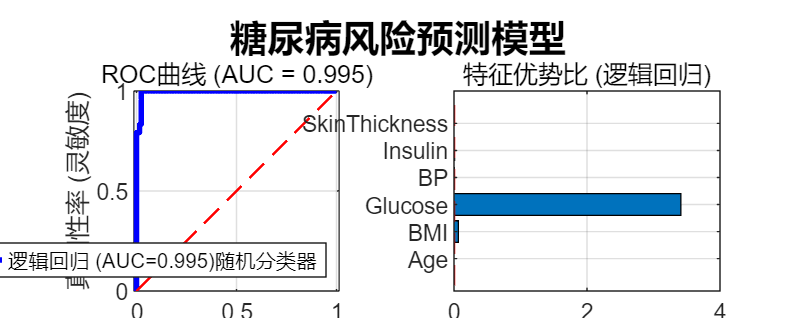


% 5.5 ROC曲线
% 计算ROC曲线
[X_roc, Y_roc, T_roc, AUC] = perfcurve(y_test, y_pred_prob_test, 1);

% 可视化
figure('Position', [100, 100, 1000, 400])

subplot(1, 2, 1)
plot(X_roc, Y_roc, 'b-', 'LineWidth', 2)
hold on
plot([0, 1], [0, 1], 'r--', 'LineWidth', 1) % 随机分类器线
xlabel('假阳性率 (1-特异度)')
ylabel('真阳性率 (灵敏度)')
title(['ROC曲线 (AUC = ', num2str(AUC, '%.3f'), ')'])
legend(['逻辑回归 (AUC=', num2str(AUC, '%.3f'), ')', '随机分类器'], 'Location', 'southeast')
grid on
axis equal

% 5.6 特征重要性（逻辑回归）
subplot(1, 2, 2)
% 提取系数（排除截距）
coefficients = logistic_model.Coefficients.Estimate(2:end);
odds_ratios = exp(coefficients);

% 绘制优势比
barh(odds_ratios)
set(gca, 'YTick', 1:length(coefficients))
set(gca, 'YTickLabel', {'Age', 'BMI', 'Glucose', 'BP', 'Insulin', 'SkinThickness'})
xlabel('优势比 (OR)')
title('特征优势比 (逻辑回归)')
grid on

% 添加参考线（OR=1表示无影响）
hold on
plot([1, 1], [0, length(coefficients)+1], 'r--', 'LineWidth', 1)

sgtitle('糖尿病风险预测模型', 'FontSize', 14, 'FontWeight', 'bold')


%% 第六部分：模型评估与验证
% 6.1 交叉验证
disp(' ')

disp('=== 模型评估与验证 ===')

=== 模型评估与验证 ===


disp('--- K折交叉验证 ---')

--- K折交叉验证 ---



% 创建交叉验证分区
cv = cvpartition(y, 'KFold', 5);

% 初始化存储变量
cv_accuracy = zeros(cv.NumTestSets, 1);
cv_precision = zeros(cv.NumTestSets, 1);
cv_recall = zeros(cv.NumTestSets, 1);
cv_f1 = zeros(cv.NumTestSets, 1);

% 执行交叉验证
for i = 1:cv.NumTestSets
    % 获取训练/测试索引
    train_idx_cv = training(cv, i);
    test_idx_cv = test(cv, i);
    
    % 分割数据
    X_train_cv = X_scaled(train_idx_cv, :);
    y_train_cv = y(train_idx_cv);
    X_test_cv = X_scaled(test_idx_cv, :);
    y_test_cv = y(test_idx_cv);
    
    % 训练逻辑回归模型
    model_cv = fitglm(X_train_cv, y_train_cv, 'Distribution', 'binomial', 'Link', 'logit');
    
    % 预测
    y_pred_prob_cv = predict(model_cv, X_test_cv);
    y_pred_cv = y_pred_prob_cv > 0.5;
    
    % 计算指标
    [cv_accuracy(i), cv_precision(i), cv_recall(i), cv_f1(i)] = ...
        calculate_metrics(y_test_cv, y_pred_cv);
end

% 显示交叉验证结果
disp('交叉验证结果:')

交叉验证结果:


disp('折数  准确率  精确率  召回率  F1分数')

折数  准确率  精确率  召回率  F1分数


for i = 1:cv.NumTestSets
    disp([num2str(i), '      ', num2str(cv_accuracy(i), '%.3f'), '    ', ...
          num2str(cv_precision(i), '%.3f'), '    ', num2str(cv_recall(i), '%.3f'), '    ', ...
          num2str(cv_f1(i), '%.3f')])
end

1      0.940    0.875    0.778    0.824
2      0.960    0.889    0.889    0.889
3      0.950    0.810    0.944    0.872
4      0.960    0.938    0.833    0.882
5      0.960    0.938    0.833    0.882



disp(' ')

disp(['平均准确率: ', num2str(mean(cv_accuracy), '%.3f'), ' ± ', num2str(std(cv_accuracy), '%.3f')])

平均准确率: 0.954 ± 0.009


disp(['平均F1分数: ', num2str(mean(cv_f1), '%.3f'), ' ± ', num2str(std(cv_f1), '%.3f')])

平均F1分数: 0.870 ± 0.027



% 6.2 模型比较
disp(' ')

disp('--- 模型比较 ---')

--- 模型比较 ---



% 训练一个简单模型（仅使用血糖）
simple_model = fitglm(X_scaled(:, 3), y, 'Distribution', 'binomial', 'Link', 'logit');
y_pred_simple = predict(simple_model, X_scaled(:, 3)) > 0.5;
[acc_simple, ~, ~, f1_simple] = calculate_metrics(y, y_pred_simple);

disp(['简单模型（仅血糖）准确率: ', num2str(acc_simple, '%.3f')])

简单模型（仅血糖）准确率: 0.844


disp(['完整模型准确率: ', num2str(acc_test, '%.3f')])

完整模型准确率: 0.960


disp(['提升: ', num2str(100*(acc_test - acc_simple)/acc_simple, '%.1f'), '%'])

提升: 13.7%


## 第七部分：课程总结与作业


% 7.1 本节课重点总结
disp(' ')

disp('=== 课程总结 ===')

=== 课程总结 ===


disp('本节课学习了:')

本节课学习了:


disp('✓ 线性回归：从简单到多元，特征重要性分析')

✓ 线性回归：从简单到多元，特征重要性分析


disp('✓ 聚类分析：K-means算法，肘部法则，结果解释')

✓ 聚类分析：K-means算法，肘部法则，结果解释


disp('✓ 主成分分析：降维，可视化，特征提取')

✓ 主成分分析：降维，可视化，特征提取


disp('✓ 逻辑回归：二分类问题，ROC曲线，模型评估')

✓ 逻辑回归：二分类问题，ROC曲线，模型评估


disp('✓ 交叉验证：模型稳定性评估')

✓ 交叉验证：模型稳定性评估


disp('✓ 完整实战案例：糖尿病风险预测模型')

✓ 完整实战案例：糖尿病风险预测模型



% 7.2 美赛建模建议
disp(' ')

disp('=== 美赛建模建议 ===')

=== 美赛建模建议 ===


disp('1. 从简单模型开始，逐步增加复杂度')

1. 从简单模型开始，逐步增加复杂度


disp('2. 始终划分训练集/测试集，避免过拟合')

2. 始终划分训练集/测试集，避免过拟合


disp('3. 使用交叉验证评估模型稳定性')

3. 使用交叉验证评估模型稳定性


disp('4. 可视化结果，便于理解和报告撰写')

4. 可视化结果，便于理解和报告撰写


disp('5. 解释模型结果，不要只关注预测精度')

5. 解释模型结果，不要只关注预测精度



% 7.3 课后作业
disp(' ')

disp('=== 课后作业 ===')

=== 课后作业 ===


disp('任务1：优化糖尿病预测模型')

任务1：优化糖尿病预测模型


disp('  1. 尝试不同的特征组合')

  1. 尝试不同的特征组合


disp('  2. 调整逻辑回归阈值，观察性能变化')

  2. 调整逻辑回归阈值，观察性能变化


disp('  3. 尝试其他分类算法（决策树、SVM等）')

  3. 尝试其他分类算法（决策树、SVM等）



disp(' ')

disp('任务2：聚类分析扩展')

任务2：聚类分析扩展


disp('  1. 尝试不同的K值，比较聚类结果')

  1. 尝试不同的K值，比较聚类结果


disp('  2. 使用轮廓系数评估聚类质量')

  2. 使用轮廓系数评估聚类质量


disp('  3. 尝试层次聚类，与K-means比较')

  3. 尝试层次聚类，与K-means比较



disp(' ')

disp('任务3：综合报告撰写')

任务3：综合报告撰写


disp('  1. 将分析过程整理成报告')

  1. 将分析过程整理成报告


disp('  2. 解释每个步骤的数学原理')

  2. 解释每个步骤的数学原理


disp('  3. 讨论模型局限性及改进方向')

  3. 讨论模型局限性及改进方向



% 7.4 下节课预告
disp(' ')

disp('=== 下节课预告 ===')

=== 下节课预告 ===


disp('主题：高级建模技术与优化')

主题：高级建模技术与优化


disp('内容：')

内容：


disp('1. 时间序列分析与预测')

1. 时间序列分析与预测


disp('2. 决策树与随机森林')

2. 决策树与随机森林


disp('3. 支持向量机(SVM)')

3. 支持向量机(SVM)


disp('4. 模型集成与优化')

4. 模型集成与优化


disp('5. 案例：传染病传播预测')

5. 案例：传染病传播预测


function [accuracy, precision, recall, f1] = calculate_metrics(y_true, y_pred)
    % 计算混淆矩阵
    TP = sum(y_true & y_pred);
    FP = sum(~y_true & y_pred);
    TN = sum(~y_true & ~y_pred);
    FN = sum(y_true & ~y_pred);
    
    % 计算指标
    accuracy = (TP + TN) / (TP + FP + TN + FN);
    precision = TP / (TP + FP);
    recall = TP / (TP + FN);
    f1 = 2 * (precision * recall) / (precision + recall);
end
function ari = rand_index(cluster1, cluster2)
    % 计算调整兰德指数
    n = length(cluster1);
    
    % 构建列联表
    max1 = max(cluster1);
    max2 = max(cluster2);
    cont_table = zeros(max1, max2);
    
    for i = 1:n
        cont_table(cluster1(i), cluster2(i)) = cont_table(cluster1(i), cluster2(i)) + 1;
    end
    
    % 计算各种和
    row_sum = sum(cont_table, 2);
    col_sum = sum(cont_table, 1);
    
    % 计算各种组合数
    n_ij = sum(cont_table(:).*(cont_table(:)-1)/2);
    n_i = sum(row_sum.*(row_sum-1)/2);
    n_j = sum(col_sum.*(col_sum-1)/2);
    
    % 计算期望指数
    n_total = n*(n-1)/2;
    expected_index = n_i * n_j / n_total;
    
    % 计算调整兰德指数
    max_index = (n_i + n_j) / 2;
    ari = (n_ij - expected_index) / (max_index - expected_index);
end